Goal is to take trackmate tracks and overlay them on the kymograph to see how well tracking works for analysing speeds and trajectories

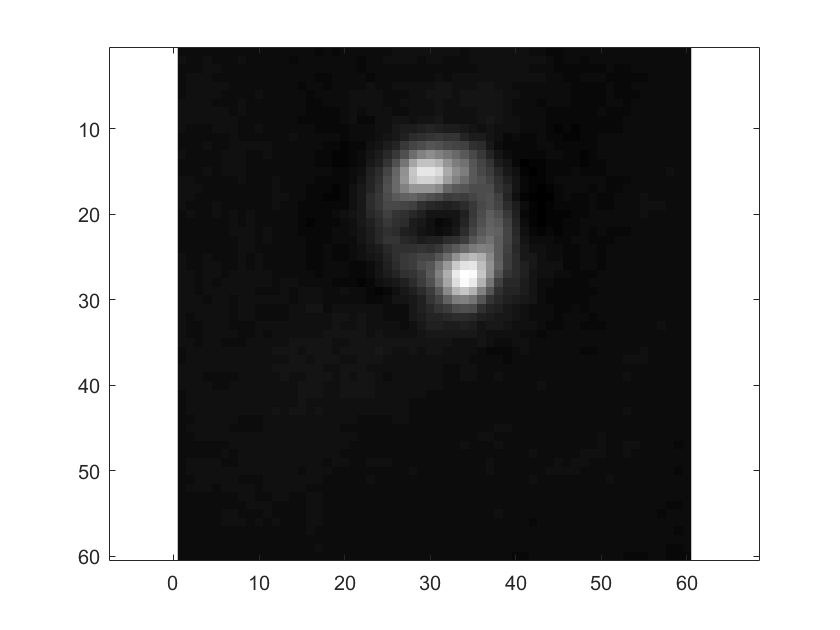

fname_tracks = 'analysed/180327_Sam1_1mW_RingHiLO_2_MMStack_Pos0_Tracks.xml';
fname_kymo = 'analysed/180327_Sam1_1mW_RingHiLO_2_MMStack_Pos0.ome_denoise_reg_ring11_kymo.tif';
fname_fit = 'analysed/180327_Sam1_1mW_RingHiLO_2_MMStack_Pos0.ome_denoise_reg_ring11_fitData.mat';
fname_im = 'analysed/180327_Sam1_1mW_RingHiLO_2_MMStack_Pos0.ome_denoise_reg_ring11_bgsub.tif';
clipz=true;
[tracks, metadata] = importTrackMateTracks(fname_tracks,clipz);
imS = imreadstack(fname_im);

im = imS(:,:,1);
figure;
imagesc(im);
colormap('gray');
axis equal;

test plot all the tracks

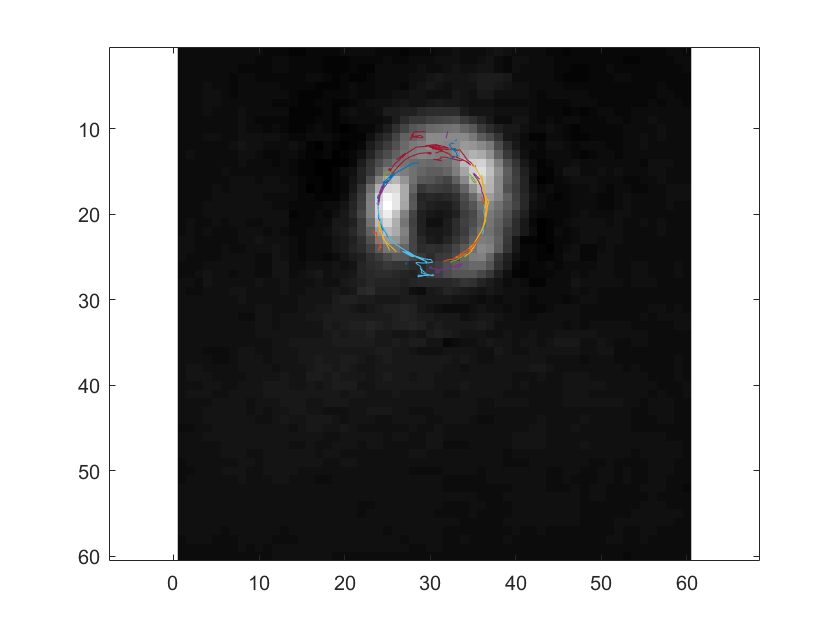

im = imS(:,:,end);
figure;
figure;
imagesc(im);
colormap('gray');
axis equal;
hold all;

pixSz = 0.065;
nTrack = numel(tracks);
for ii = 1:nTrack
    tr = tracks{ii};
    xPix = tr(:,2)/pixSz;
    yPix = tr(:,3)/pixSz;
    plot(xPix,yPix,'-');
end

now try to calculate angles for each track, based on the current fitted centre 

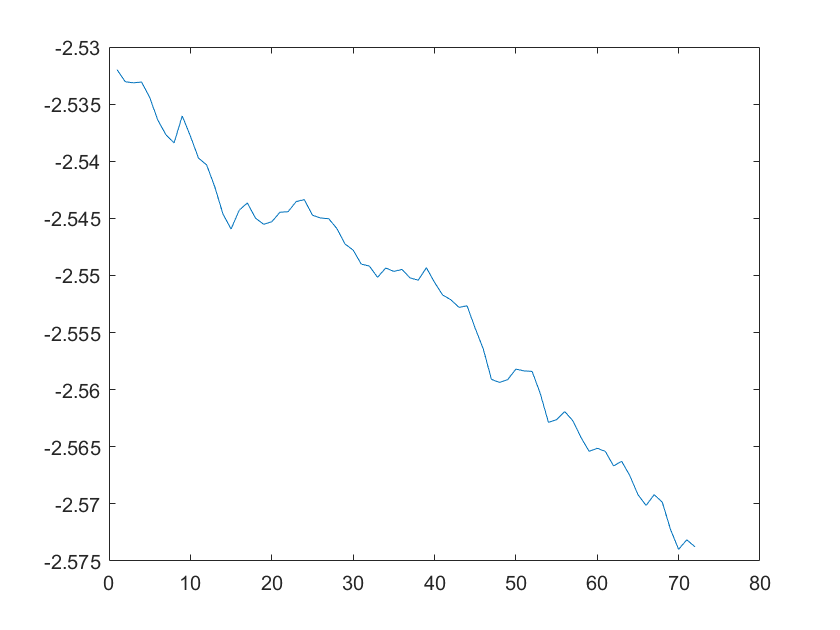

data = load(fname_fit);
circFit = data.circFit;
tr = tracks{1};
[trackCirc1,theta]= getTrackAngle(tr,circFit);
fr = tr(:,1)+1;
figure;plot(fr,theta,'-');

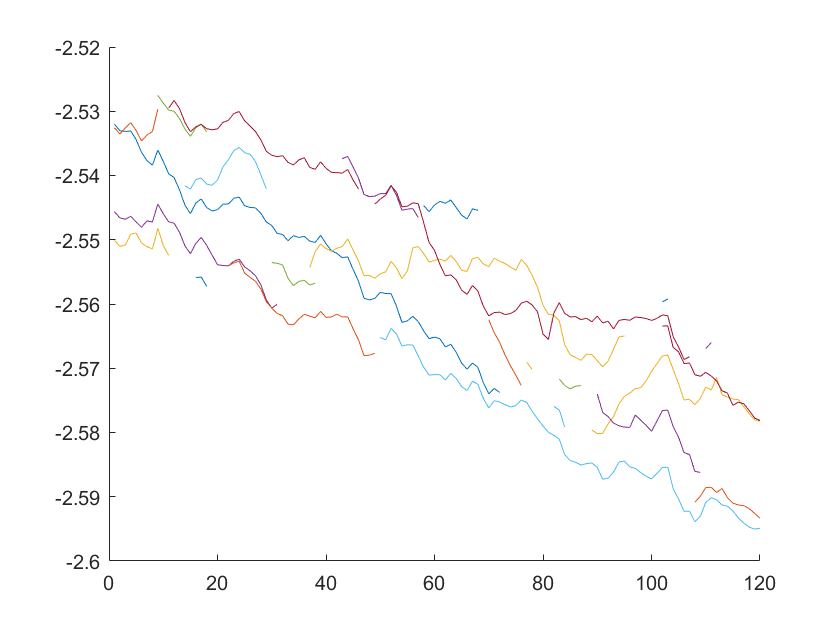


for ii = 1:nTrack
    trackCirc{ii,1}=getTrackAngle(tracks{ii},circFit);
end
 
figure;hold all;
for ii = 1:nTrack
    tr = trackCirc{ii,1};
    theta = tr(:,4);
    fr = tr(:,1)+1;
    plot(fr,theta,'-');
end

the initial attempt is not working because the x0 y0 coords and xy coords do not match. Try plotting x0 y0 over the ring image (since we already plotted the xy)